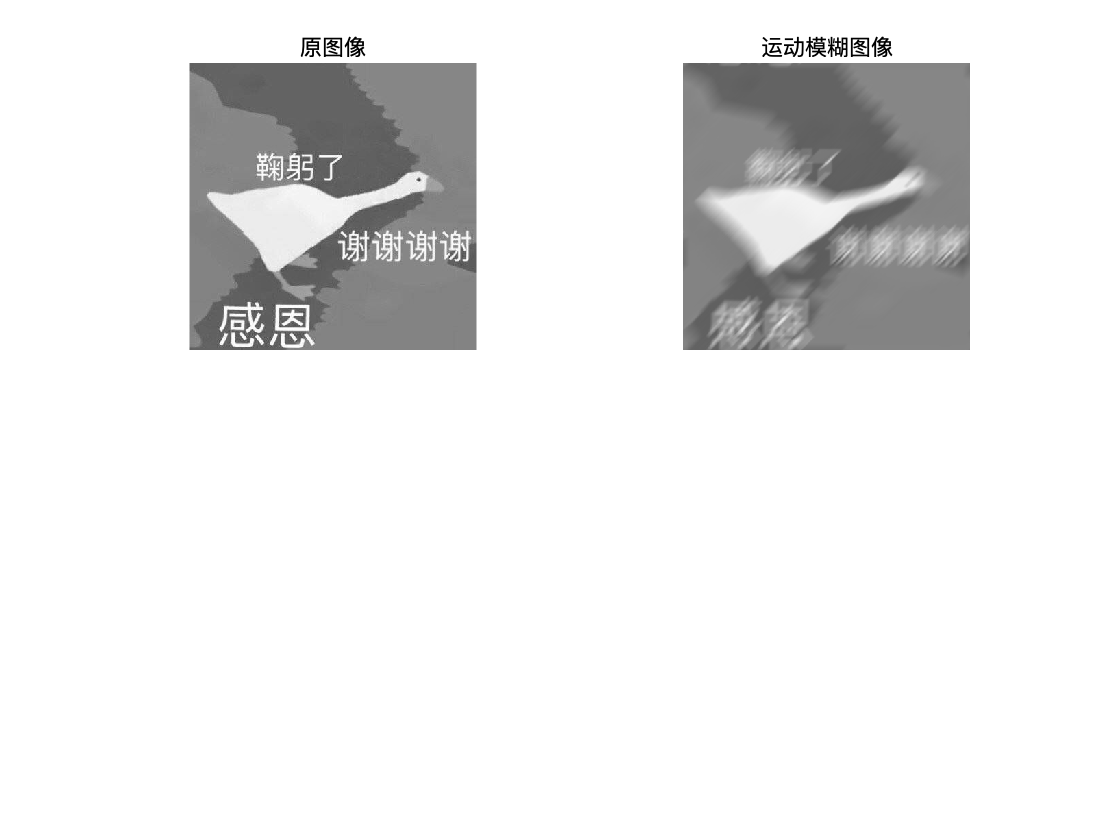

A=rgb2gray(imread('pic.jpg'));
subplot(221);imshow(A);title("原图像")

LEN=30;THEAT=45;
PSF=fspecial('motion',LEN,THEAT);
MF=imfilter(A,PSF,'circular','conv');
subplot(222);imshow(MF);title("运动模糊图像")


imwrite(MF,'pic2.jpg');

% 估计函数复原

% 维纳滤波复原
MF=im2double(MF);
noise=imnoise(zeros(size(MF)),'gaussian');
MFN=MF+noise;
figure();
subplot(221);imshow(MF,[]);title("运动模糊图像")
subplot(222);imshow(MFN,[]);title("运动模糊加高斯")
NSR=sum(noise(:).^2)/sum(MFN(:).^2);
subplot(223);imshow(deconvwnr(MFN,PSF),[]);title("逆滤波")
subplot(224);imshow(deconvwnr(MFN,PSF,NSR),[]);title("维纳滤波")